fs = 4800;
t = 0:1/fs:1;
f = 50;
w = 2*f;
x = sin(w*t)

x =          0    0.0208    0.0417    0.0625    0.0832    0.1040    0.1247    0.1453    0.1659    0.1864    0.2068    0.2272    0.2474    0.2675    0.2875    0.3074    0.3272    0.3468    0.3663    0.3856    0.4047    0.4237    0.4425    0.4610    0.4794    0.4976    0.5156    0.5333    0.5508    0.5681    0.5851    0.6019    0.6184    0.6346    0.6506    0.6662    0.6816    0.6967    0.7115    0.7260    0.7402    0.7540    0.7675    0.7807    0.7936    0.8061    0.8182    0.8300    0.8415    0.8525


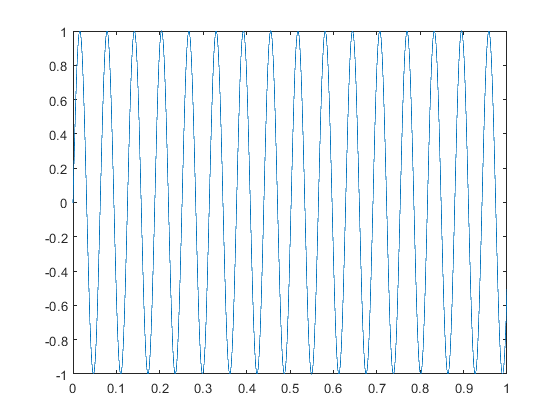

plot(t,x)

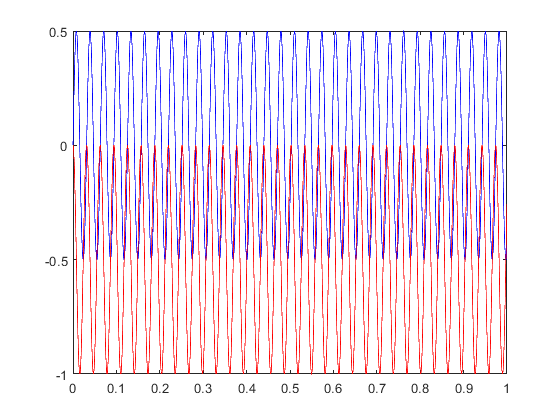


% the 50 Hz bin
xe = x.*exp(-1i*w.*t);
plot(t,real(xe),'b',t,imag(xe),'r')

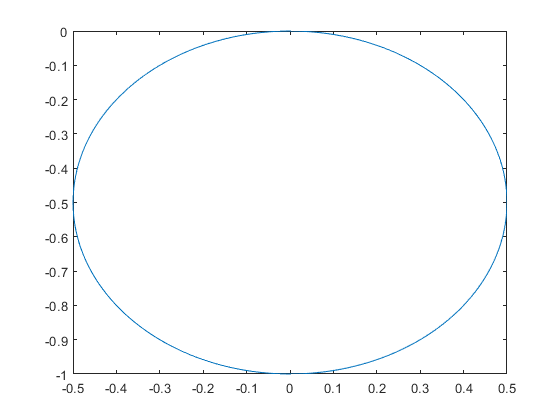

plot(xe)

sum(xe), abs(sum(xe))/fs,angle(sum(xe))

ans = 5.9345e+00 - 2.4106e+03i

ans = 0.5022

ans = -1.5683

experiments in the Z-domain

n = 1:60

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


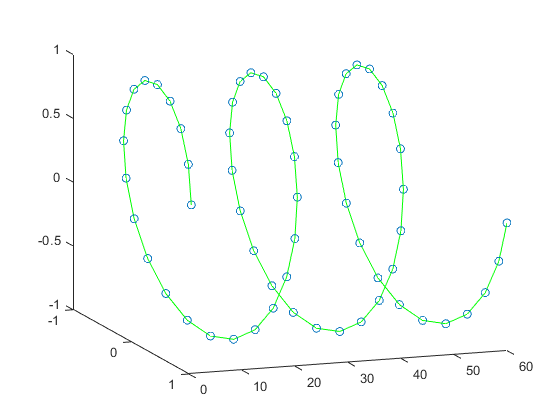

w0 = pi/10;
z = exp(1i*w0); x = z.^n;
plot3(n,real(x),imag(x),'o')
hold on
plot3(n,real(x),imag(x),'-g')
hold off
view(20,-15)

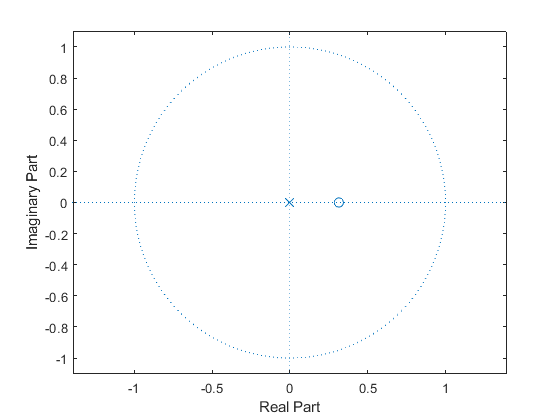

zplane(w0,0)